## 2.1 Tune

% under 1A
tone2freq(1,0,0) % A

ans = 440

tone2freq(3,1,0) % C+8

ans = 1.0465e+03

tone2freq(4,0,1) % D#

ans = 622.2540

## 2.2 Scaled

tone2scaledfreq(1,'B',0,0) % under 1B, B

ans = 493.8833

tone2scaledfreq(3,'C',1,0) % under 1C, E

ans = 659.2551

tone2scaledfreq(6,'F',0,-1) % under 1F, Cb

ans = 554.3653

for i = 1:15
    tone2scaledfreq(i,'A',0,0)
end

ans = 440

ans = 493.8833

ans = 523.2511

ans = 587.3295

ans = 659.2551

ans = 698.4565

ans = 783.9909

ans = 880

ans = 987.7666

ans = 1.0465e+03

ans = 1.1747e+03

ans = 1.3185e+03

ans = 1.3969e+03

ans = 1.5680e+03

ans = 1760

## 3.1 Generate Wave

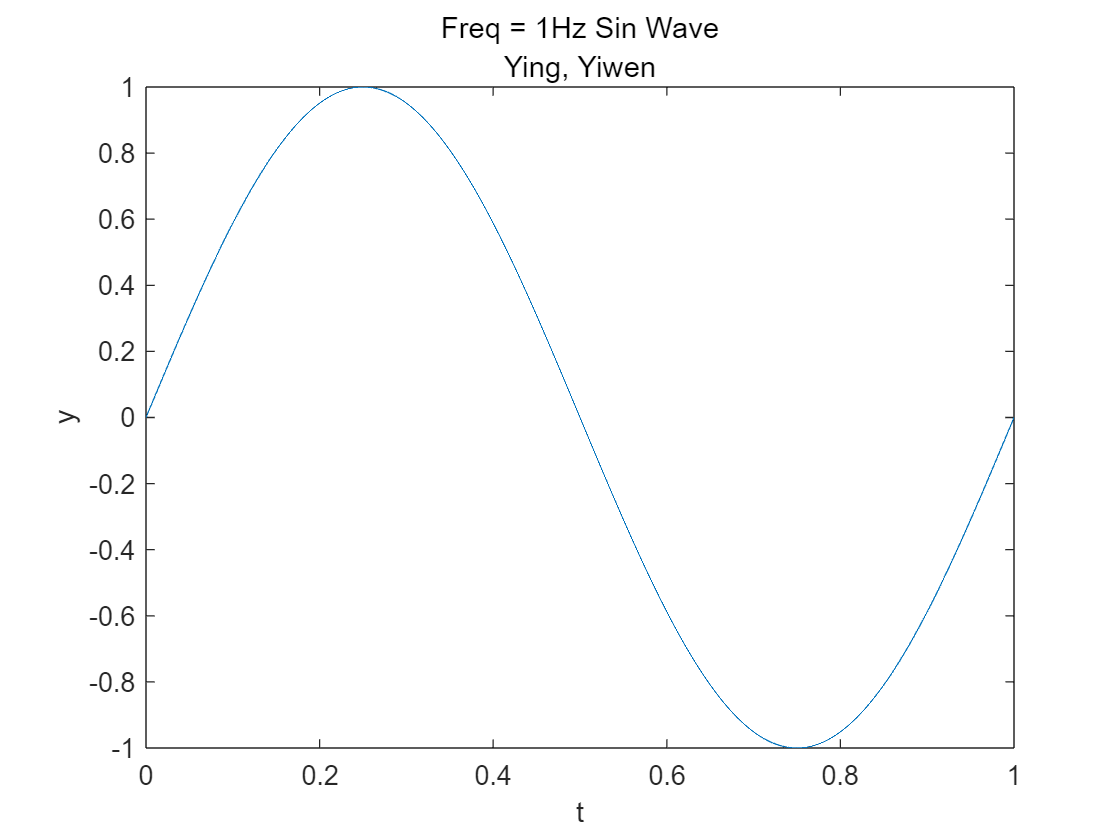

fs = 8192; f = 1; T = 1/f; 
t = linspace(0, T, fs);
y = sin(2*pi*f*t);
figure;
plot(t,y),xlabel('t'),ylabel('y'),title('Freq = 1Hz Sin Wave','Ying, Yiwen');
saveas(gcf, '311.png');

sound(y,fs);
pause(length(y)/fs);

No sound heard.

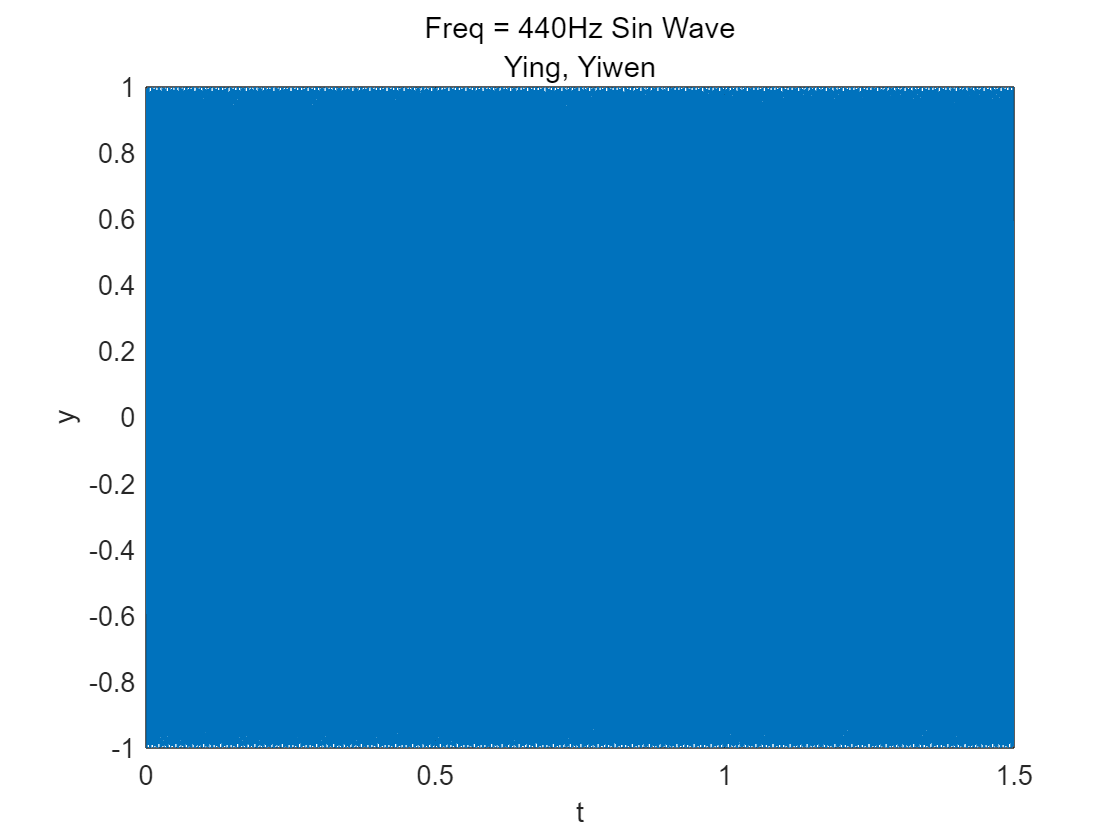

fs = 8192; f = 440; rhythm = 1.5; 
t = linspace(0, rhythm, fs*rhythm);
y = sin(2*pi*f*t);
figure;
plot(t,y),xlabel('t'),ylabel('y'),title('Freq = 440Hz Sin Wave','Ying, Yiwen');
saveas(gcf, '312.png');

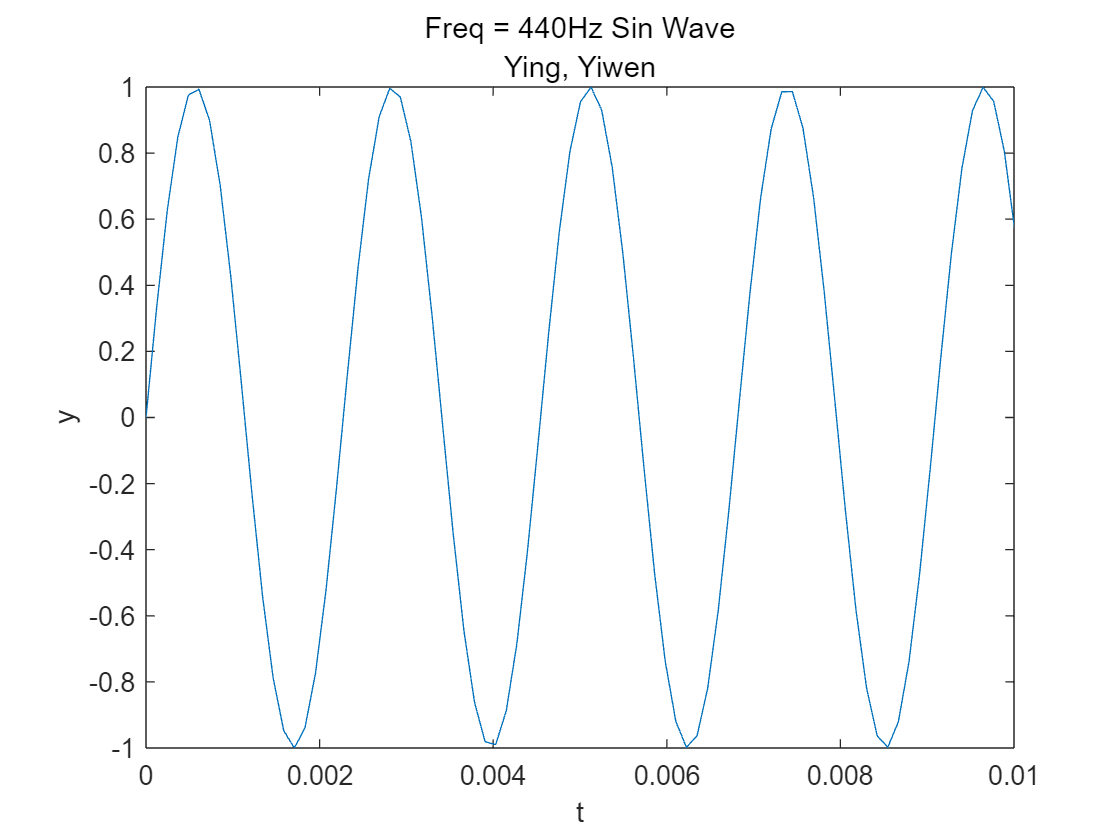

figure;
plot(t,y),xlabel('t'),ylabel('y'),title('Freq = 440Hz Sin Wave','Ying, Yiwen'),axis([0 0.01 -1 1]);
saveas(gcf, '313.png');

sound(y,fs);
pause(length(y)/fs);

Heard 'du' for about 1.5s.

## 3.2 Generate Music

% set parameter
tones = [6,7, 1,7,1,3, 7,3,3, 6,5,6,1, 5,0,3,3, 4,3,4,1,...
    3,0,1,1,1, 7,4,4,7, 7,0,6,7, 1,7,1,3, 7,0,3,3, 6,5,6,1,...
    5,0,3, 4,1,7,7,1, 2,2,3,1,0, 1,7,6,6,7,5, 6,0,1,2, 3,2,3,5,...
    2,0,5,5, 1,7,1,3, 3,0,0, 6,7,1,7,2,2, 1,5,5,0, 4,3,2,1,...
    3, 3,0,3, 6,5,5, 3,2,1,0,1, 2,1,2,2,5, 3,0,3,...
    6,5, 3,2,1,0,1, 2,1,2,2,7, 6,0,6,7, 6];
scales = 'D';
noctaves = [0,0, 1,0,1,1, 0,0,0, 0,0,0,1, 0,0,0,0, 0,0,0,1,...
    0,0,1,1,1, 0,0,0,0, 0,0,0,0, 1,0,1,1, 0,0,0,0, 0,0,0,1,...
    0,0,0, 0,1,0,0,1, 1,1,1,1,0, 1,0,0,0,0,0, 0,0,1,1, 1,1,1,1,...
    1,0,0,0, 1,0,1,1, 1,0,0, 0,0,1,0,1,1, 1,0,0,0, 1,1,1,1,...
    1, 1,0,1, 1,1,1, 1,1,1,0,1, 1,1,1,1,1, 1,0,1,...
    1,1, 1,1,1,0,1, 1,1,1,1,0, 0,0,0,0, 0];
risings = [0,0, 0,0,0,0, 0,0,0, 0,0,0,0, 0,0,0,0, 0,0,0,0,...
    0,0,0,0,0, 0,1,1,0, 0,0,0,0, 0,0,0,0, 0,0,0,0, 0,0,0,0,...
    0,0,0, 0,0,0,0,0, 0,0,0,0,0, 0,0,0,0,0,1, 0,0,0,0, 0,0,0,0,...
    0,0,0,0, 0,0,0,0, 0,0,0, 0,0,0,0,0,0, 0,0,0,0, 0,0,0,0,...
    0, 0,0,0, 0,0,0, 0,0,0,0,0, 0,0,0,0,0, 0,0,0,...
    0,0, 0,0,0,0,0, 0,0,0,0,0, 0,0,0,0, 0];
rhythms = [0.5,0.5, 1.5,0.5,1,1, 3,0.5,0.5, 1.5,0.5,1,1, 2,1,0.5,0.5, 1.5,0.5,0.5,1.5,...
    2,0.5,0.5,0.5,0.5, 1.5,0.5,1,1, 2,1,0.5,0.5, 1.5,0.5,1,1, 2,1,0.5,0.5, 1.5,0.5,1,1,...
    3,0.5,0.5, 1,0.5,0.5,1,1, 0.5,0.5,0.5,1,1, 1,0.5,0.5,0.5,1,1, 2,1,0.5,0.5, 1.5,0.5,1,1,...
    2,1,0.5,0.5, 0.5,0.5,1,1, 2,1,1, 0.5,0.5,1,1,0.5,0.5, 1.5,0.5,1,1, 1,1,1,1,...
    4, 2,1,1, 2,1,1, 0.5,0.5,1,0.5,0.5, 1,0.5,0.5,0.5,1, 2,1,1,...
    2,2, 0.5,0.5,2,0.5,0.5, 1,0.5,0.5,0.5,1, 2,1,0.5,0.5, 4];
fs = 44100;

% generate music and save
music_wave = gen_music(tones, scales, noctaves, risings, rhythms, fs);
sound(music_wave, fs);
audiowrite('generated_music.wav', music_wave, fs);
disp('Saved as generated_music.wav');

Saved as generated_music.wav


## 4 Attenuation

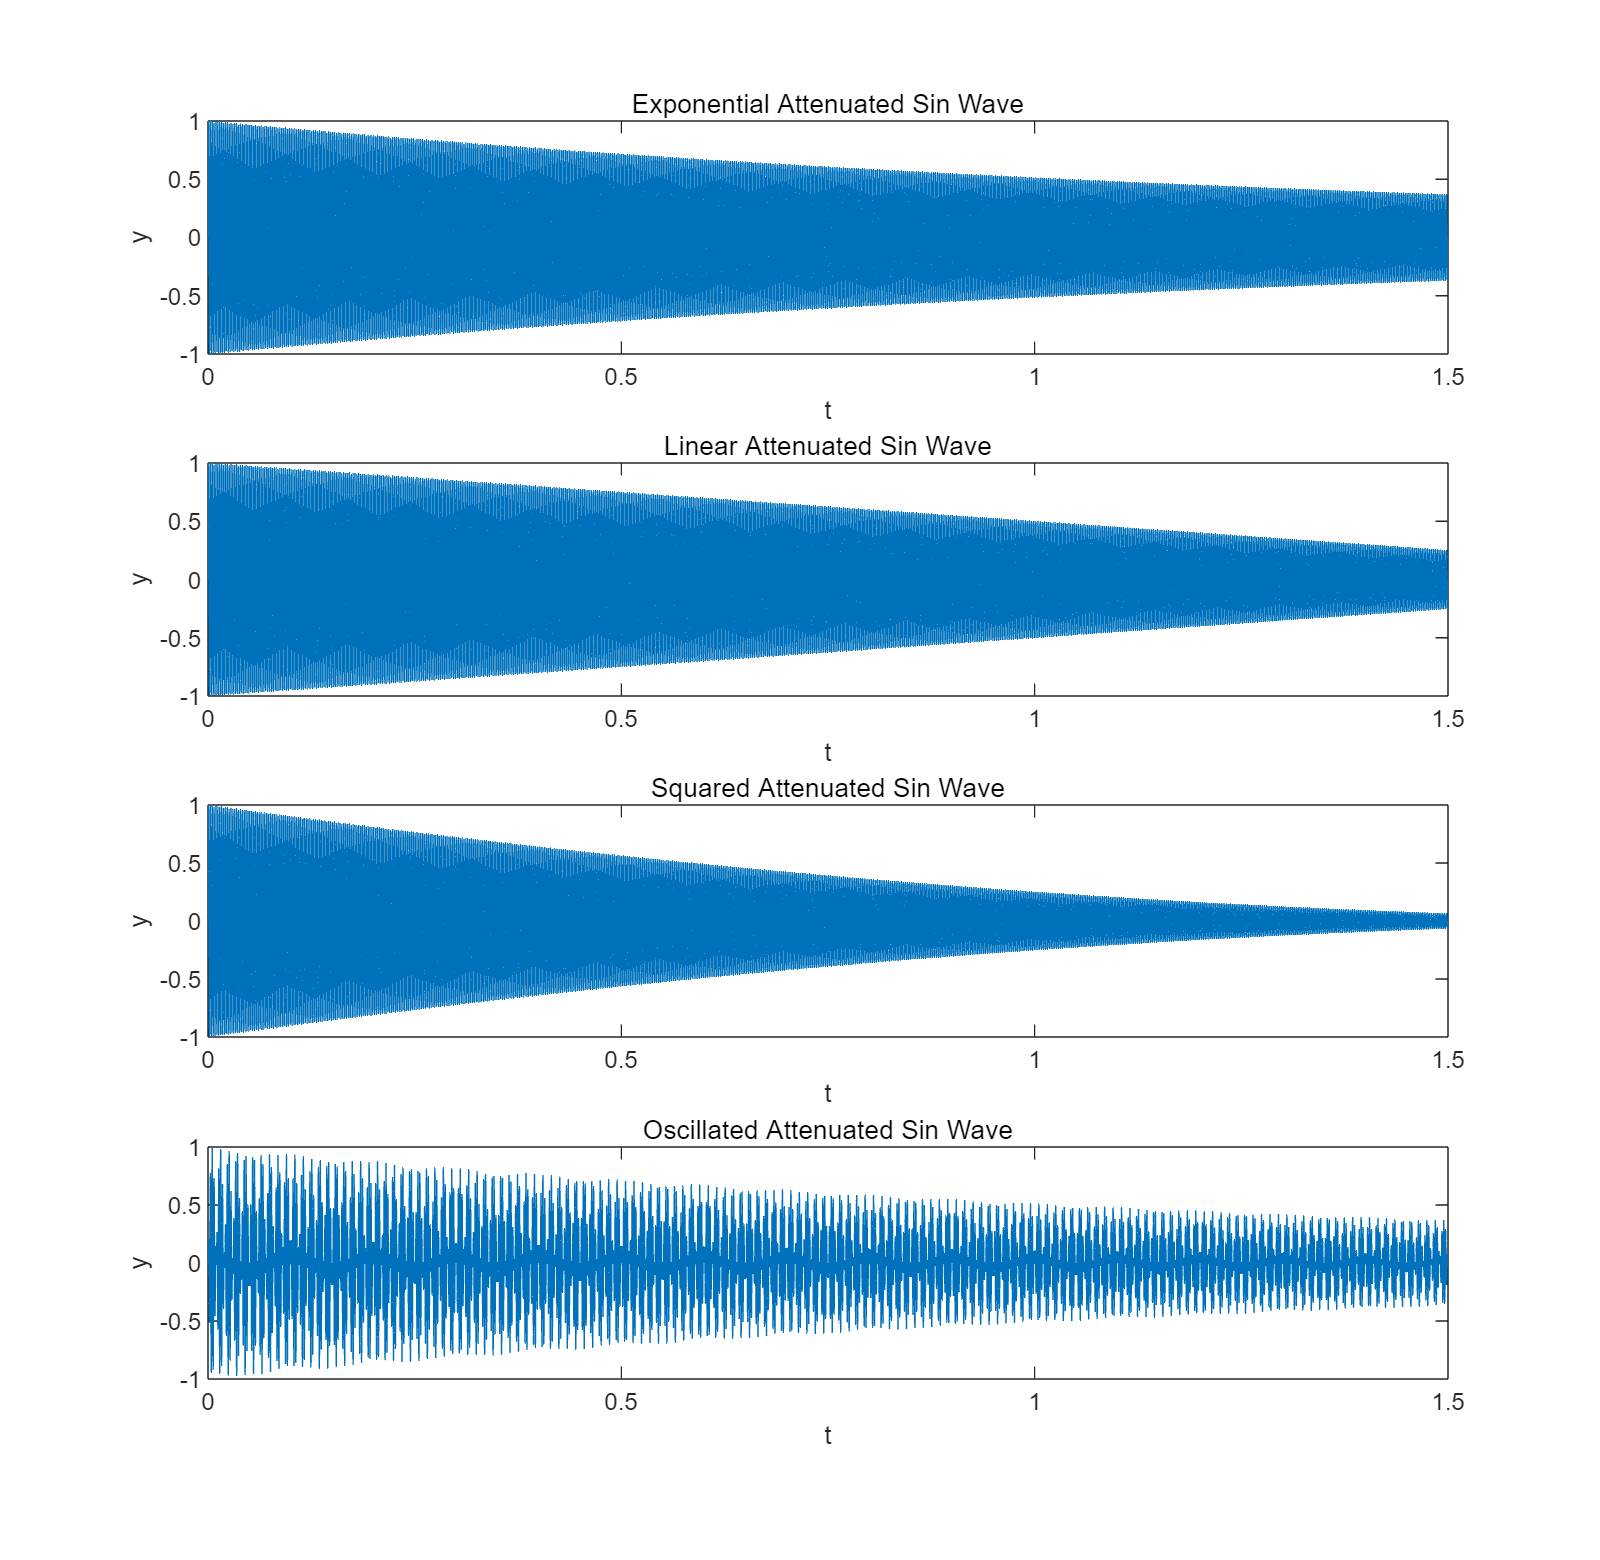

fs = 8192; f = 440; rhythm = 1.5; 
t = linspace(0, rhythm, fs*rhythm);
y = sin(2*pi*f*t);
waves1 = y .* exp(-t/rhythm); % exponential
waves2 = y .* max(0, 1-0.5*t); % linear
waves3 = y .* max(0, (1-0.5*t).^2); % squared
waves4 = y .* exp(-t/rhythm) .* sin(2*pi*50*t); % oscillating
figure('Position', [100, 100, 800, 1200]);
subplot(4,1,1),plot(t,waves1),xlabel('t'),ylabel('y'),title('Exponential Attenuated Sin Wave');
subplot(4,1,2),plot(t,waves2),xlabel('t'),ylabel('y'),title('Linear Attenuated Sin Wave');
subplot(4,1,3),plot(t,waves3),xlabel('t'),ylabel('y'),title('Squared Attenuated Sin Wave');
subplot(4,1,4),plot(t,waves4),xlabel('t'),ylabel('y'),title('Oscillated Attenuated Sin Wave');
saveas(gcf, '4.png');

sound(waves1,fs);
pause(length(waves1)/fs);
sound(waves2,fs);
pause(length(waves2)/fs);
sound(waves3,fs);
pause(length(waves3)/fs);
sound(waves4,fs);
pause(length(waves4)/fs);

Heard attenuated 'du'.

Squared attenuated have the best performance.

The third wave is very much like strings, and the fourth wave vibrates like a metal instrument.

## 5 Harmonic

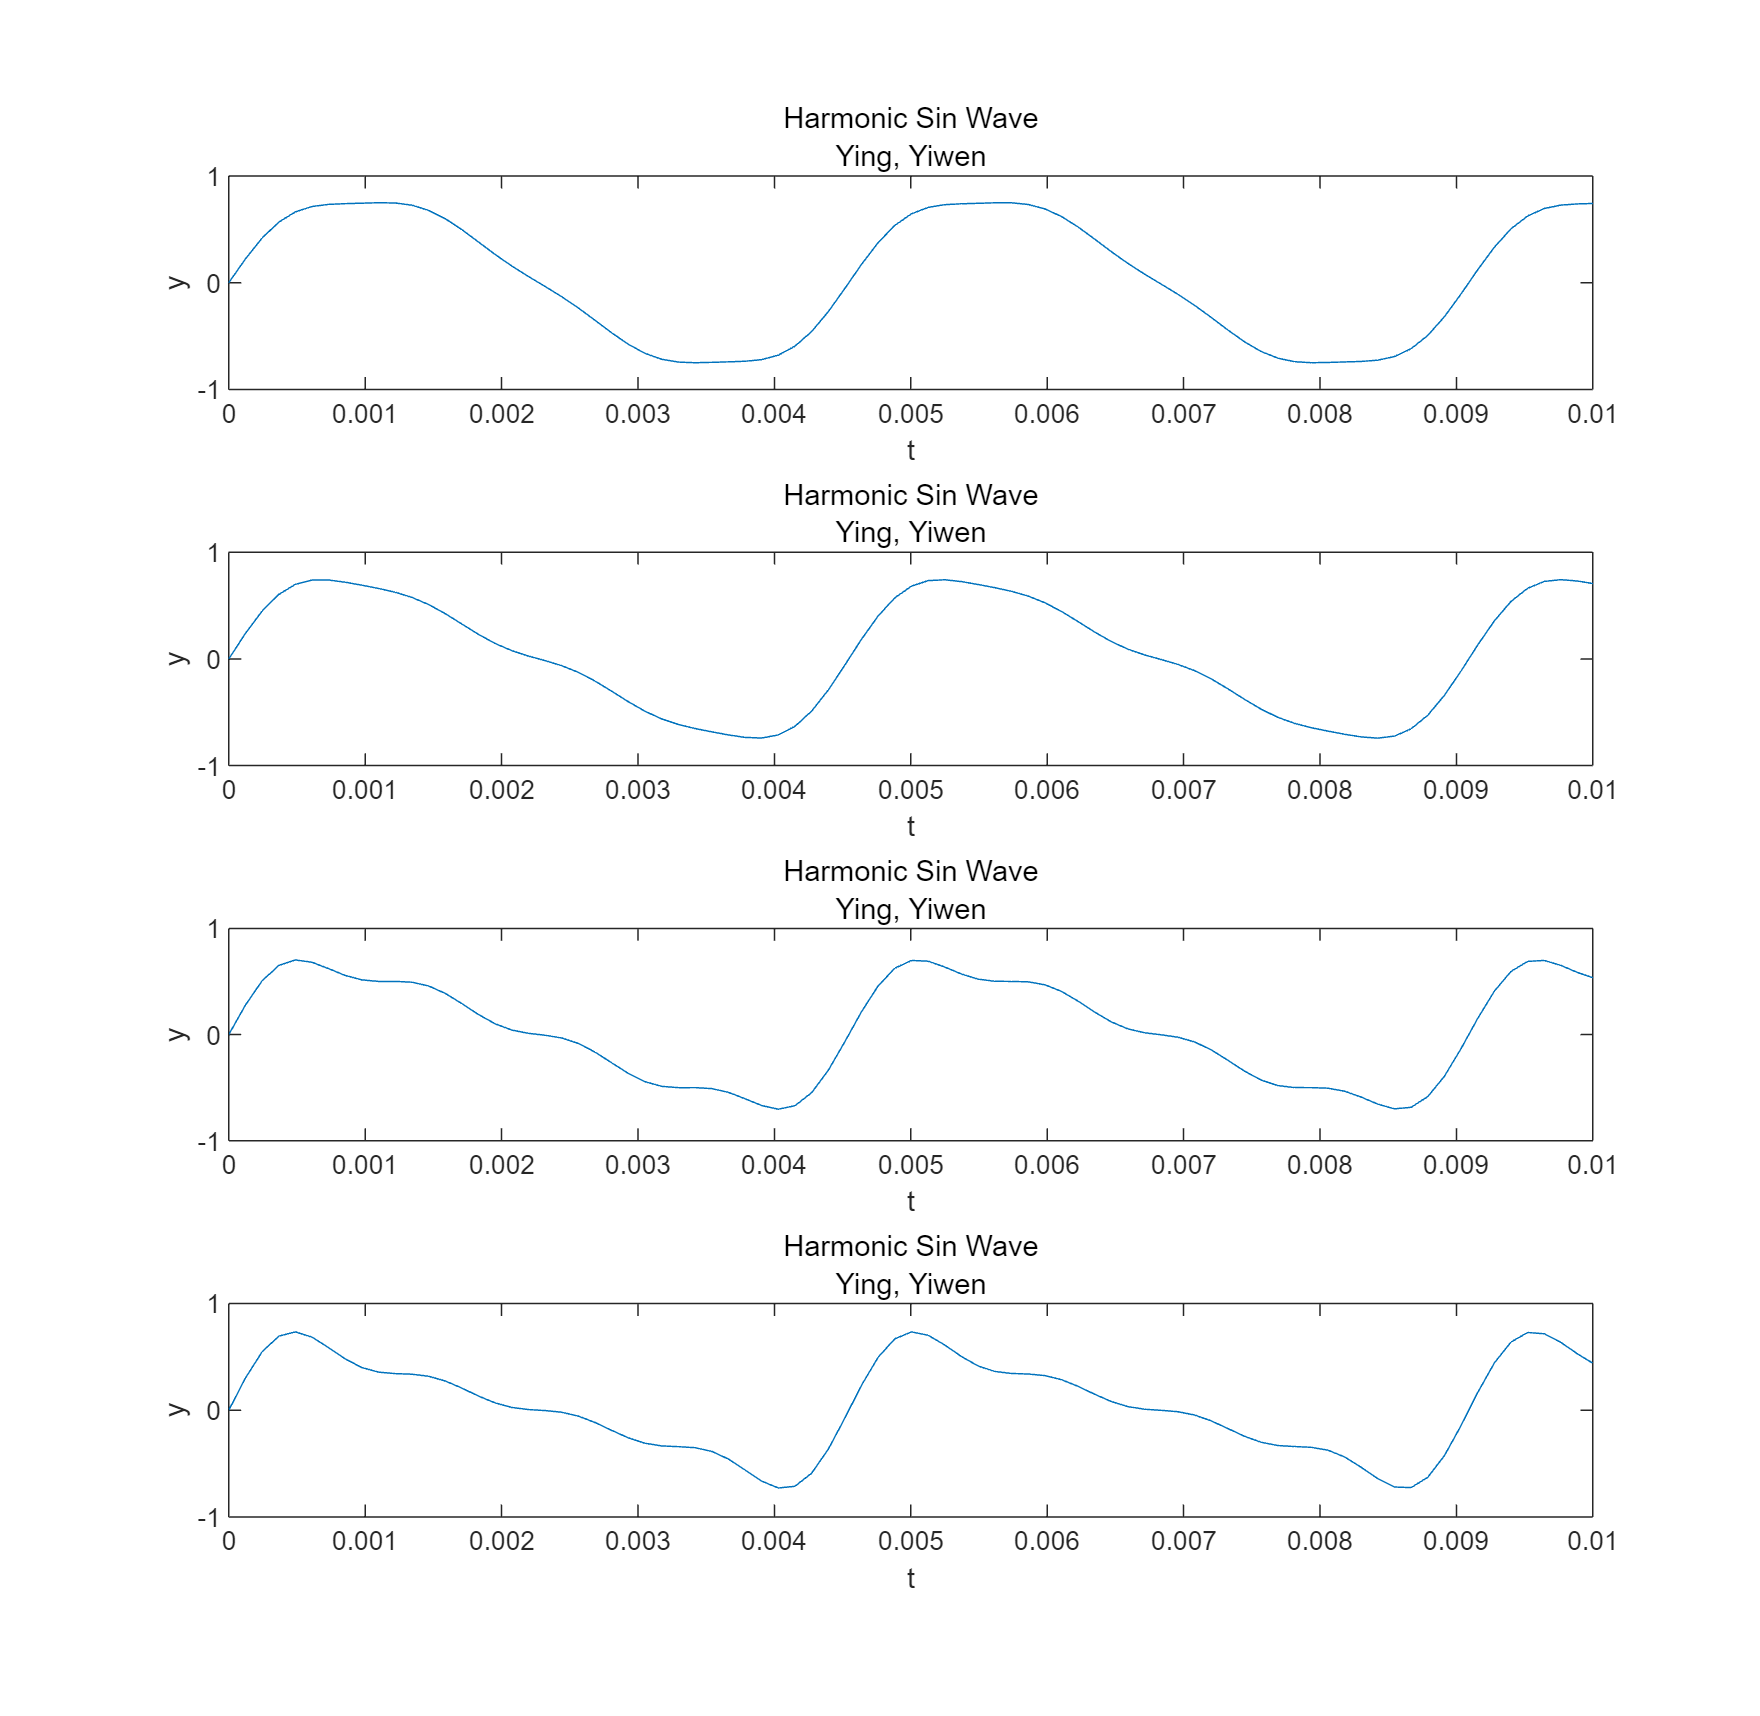

fs = 8192; f = 220; rhythm = 1; 
t = linspace(0, rhythm, fs*rhythm);
wave1 = 0.8*sin(2*pi*f*t)+0.1*sin(2*pi*2*f*t)+0.05*sin(2*pi*3*f*t)+0.05*sin(2*pi*4*f*t);
wave2 = 0.7*sin(2*pi*f*t)+0.2*sin(2*pi*2*f*t)+0.05*sin(2*pi*3*f*t)+0.05*sin(2*pi*4*f*t);
wave3 = 0.6*sin(2*pi*f*t)+0.2*sin(2*pi*2*f*t)+0.1*sin(2*pi*3*f*t)+0.1*sin(2*pi*4*f*t);
wave4 = 0.5*sin(2*pi*f*t)+0.25*sin(2*pi*2*f*t)+0.15*sin(2*pi*3*f*t)+0.1*sin(2*pi*4*f*t);
figure('Position', [100, 100, 800, 1200]);
subplot(4,1,1),plot(t,wave1),xlabel('t'),ylabel('y'),title('Harmonic Sin Wave','Ying, Yiwen'),axis([0 0.01 -1 1]);
subplot(4,1,2),plot(t,wave2),xlabel('t'),ylabel('y'),title('Harmonic Sin Wave','Ying, Yiwen'),axis([0 0.01 -1 1]);
subplot(4,1,3),plot(t,wave3),xlabel('t'),ylabel('y'),title('Harmonic Sin Wave','Ying, Yiwen'),axis([0 0.01 -1 1]);
subplot(4,1,4),plot(t,wave4),xlabel('t'),ylabel('y'),title('Harmonic Sin Wave','Ying, Yiwen'),axis([0 0.01 -1 1]);
saveas(gcf, '5.png');

sound(wave1,fs);
pause(length(wave1)/fs);
sound(wave2,fs);
pause(length(wave2)/fs);
sound(wave3,fs);
pause(length(wave3)/fs);
sound(wave4,fs);
pause(length(wave4)/fs);

wave 2 has the best performance

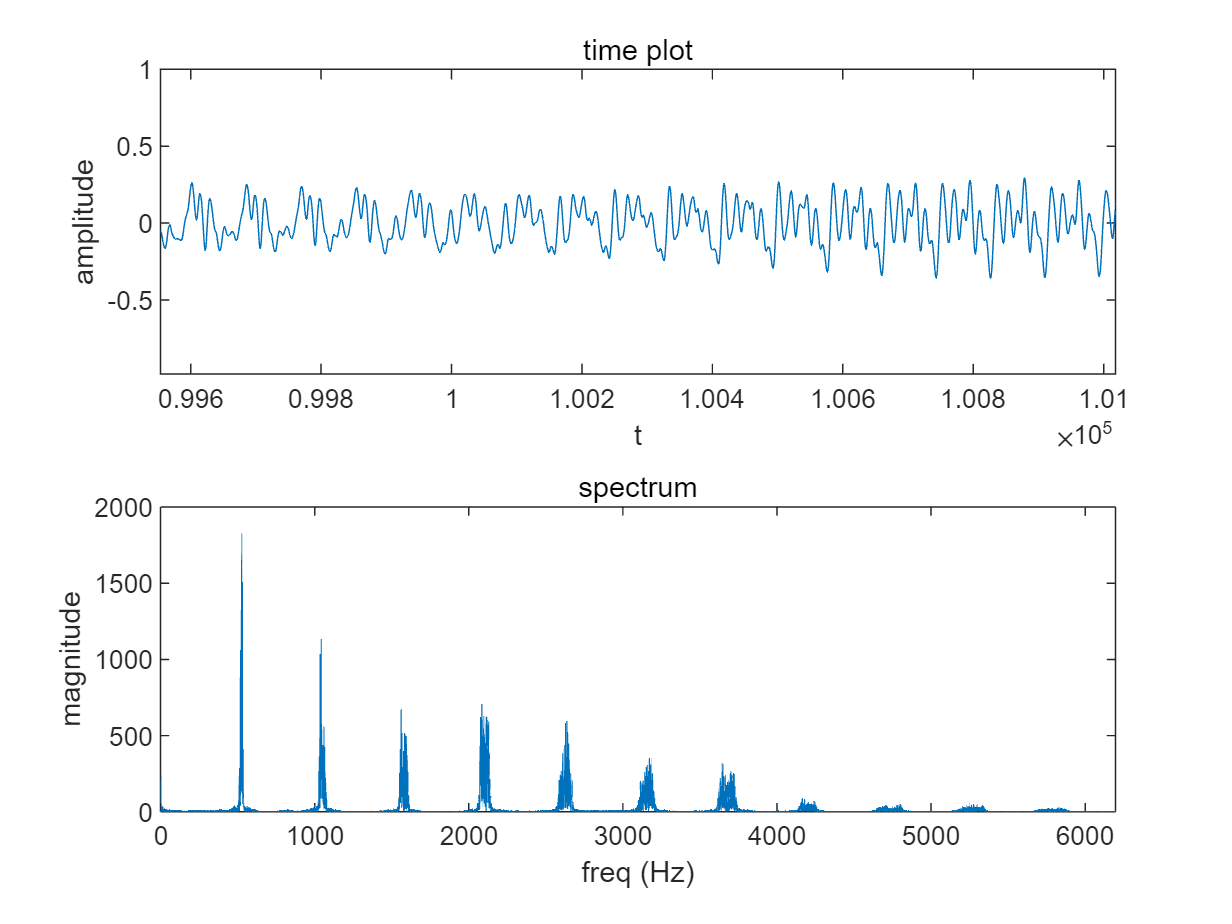

[audioData, fs] = audioread('violin.mp3');
n = length(audioData);
f = (0:n-1)*(fs/n);
audioFFT = fft(audioData);
magnitude = abs(audioFFT);
figure;
subplot(2,1,1),plot(audioData),xlabel('t'),ylabel('amplitude'),title('time plot'),axis([1e5 1e5+1000 -1 1]);
subplot(2,1,2),plot(f(1:floor(n/2)), magnitude(1:floor(n/2))),xlabel('freq (Hz)'),ylabel('magnitude'),title('spectrum'),axis([0 6000 0 2000]);
saveas(gcf,'violin.png');

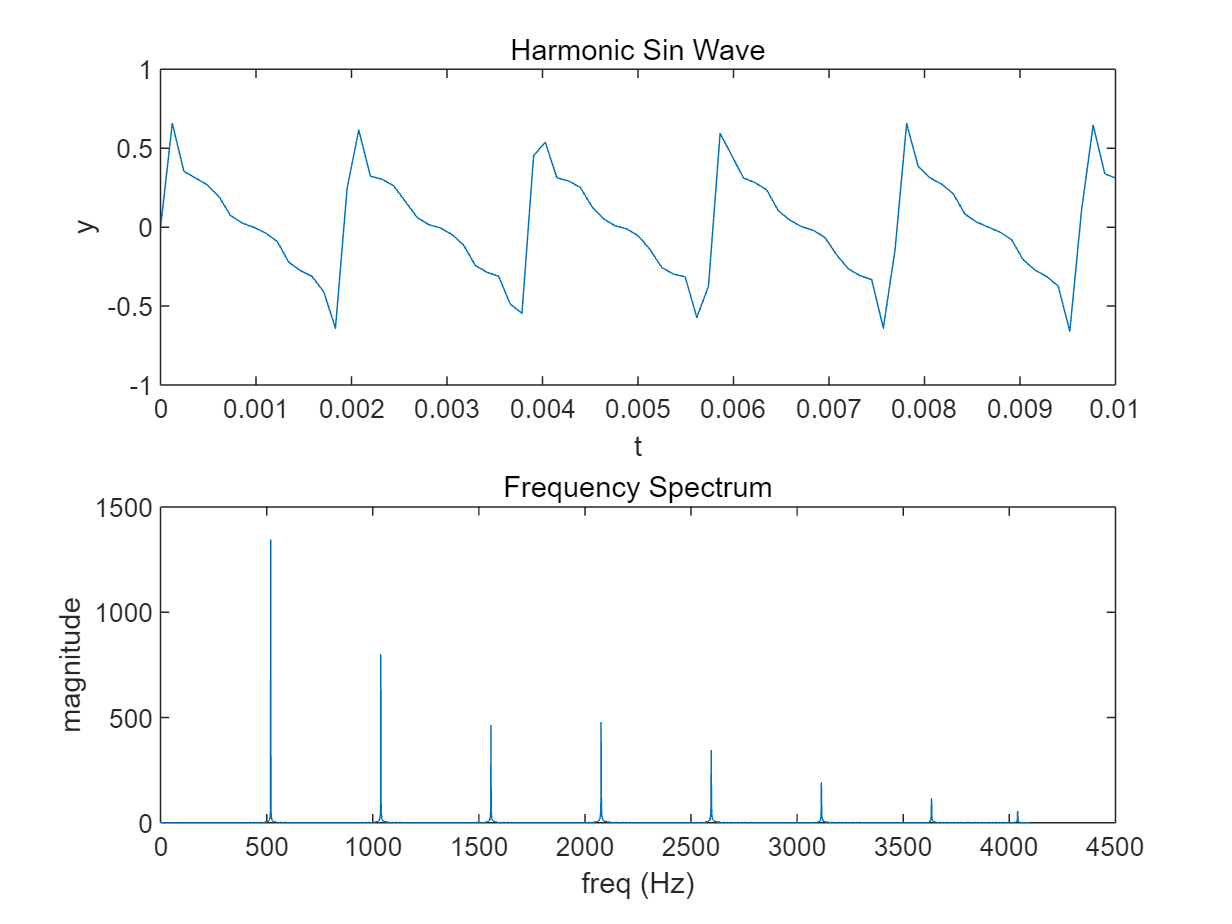

fs = 8192; f = 525; rhythm = 1; 
t = linspace(0, rhythm, fs*rhythm);
wave = 0.33*sin(2*pi*f*t)+0.20*sin(2*pi*2*f*t)+0.12*sin(2*pi*3*f*t)+0.13*sin(2*pi*4*f*t)+0.10*sin(2*pi*5*f*t)+0.06*sin(2*pi*6*f*t)+0.04*sin(2*pi*7*f*t)+0.02*sin(2*pi*8*f*t);
figure;
subplot(2,1,1),plot(t,wave),xlabel('t'),ylabel('y'),title('Harmonic Sin Wave'),axis([0 0.01 -1 1]);
n = length(wave);
frequencies = (0:n-1)*(fs/n);
wave_fft = abs(fft(wave));
subplot(2,1,2),plot(frequencies(1:floor(n/2)), wave_fft(1:floor(n/2))),xlabel('freq (Hz)'),ylabel('magnitude'),title('Frequency Spectrum');
saveas(gcf,'violin_mine.png');

sound(wave,fs);
pause(length(wave)/fs);

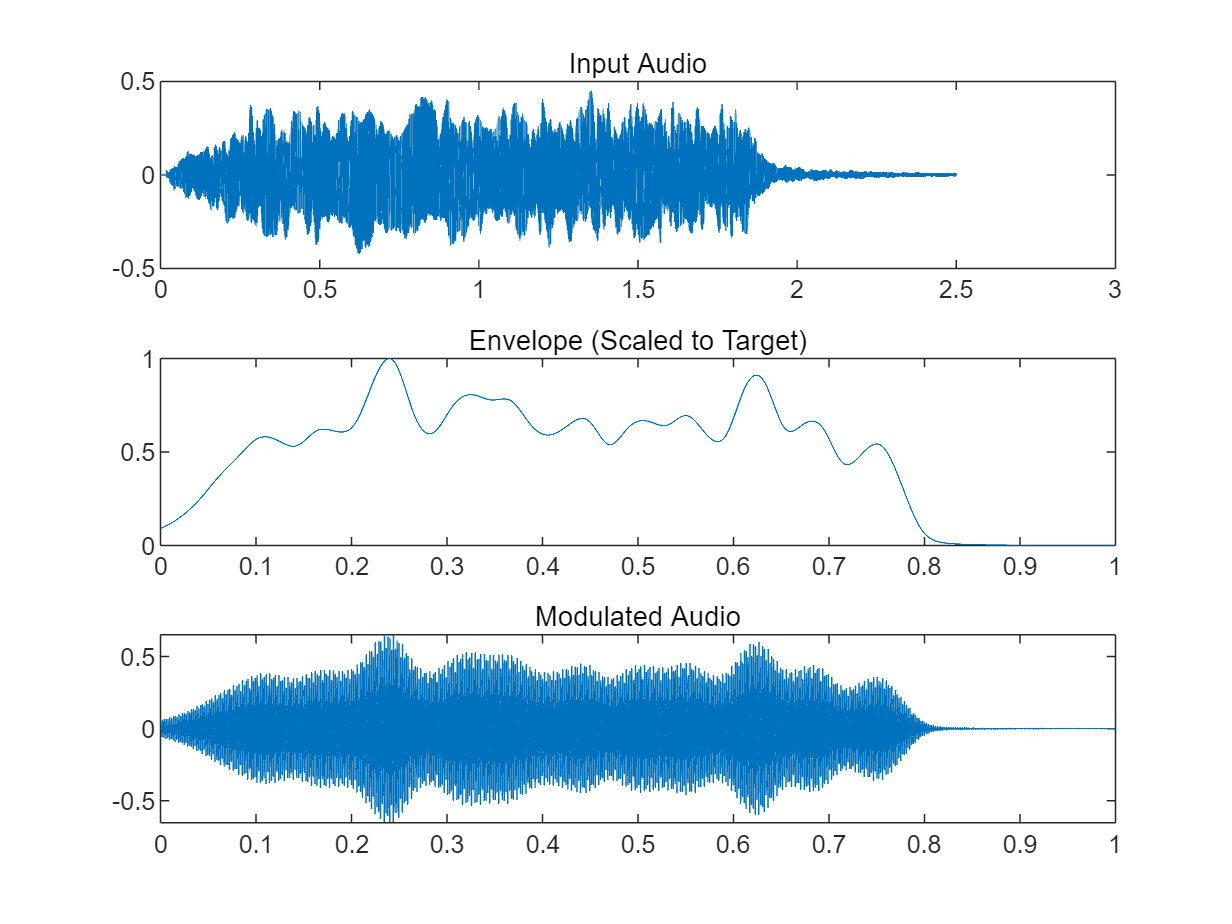

[audioData, fs_input] = audioread('violin.mp3');
start_sample = floor(1 * fs_input);
end_sample = floor(3.5 * fs_input);
audioData = audioData(start_sample:end_sample);

% 短时能量计算
frame_length = 8192; hop_length = 2048; window = hamming(frame_length);
num_frames = floor((length(audioData) - frame_length) / hop_length) + 1;
energy = zeros(1, num_frames);
for i = 1:num_frames
    start_idx = (i-1)*hop_length + 1;
    end_idx = start_idx + frame_length - 1;
    frame = audioData(start_idx:end_idx) .* window;
    energy(i) = sum(frame.^2);
end

% 目标音频信号
fs = 8192; rhythm = 1; f = 525;
t = linspace(0, rhythm, fs * rhythm);
wave = 0.33*sin(2*pi*f*t) + 0.20*sin(2*pi*2*f*t) + 0.12*sin(2*pi*3*f*t) + ...
       0.13*sin(2*pi*4*f*t) + 0.10*sin(2*pi*5*f*t) + 0.06*sin(2*pi*6*f*t) + ...
       0.04*sin(2*pi*7*f*t) + 0.02*sin(2*pi*8*f*t);

% 归一化并调整包络到目标音频长度
time_energy = linspace(0, length(audioData)/2.5*rhythm/fs_input, num_frames);
time_wave = linspace(0, rhythm, length(wave));
envelope = interp1(time_energy, energy, time_wave, 'spline');
envelope = envelope / max(envelope);

modulated_wave = wave .* envelope;

figure;
subplot(3, 1, 1), plot(linspace(0, length(audioData)/fs_input, length(audioData)), audioData), title('Input Audio');
subplot(3, 1, 2), plot(time_wave, envelope), title('Envelope (Scaled to Target)');
subplot(3, 1, 3), plot(time_wave, modulated_wave), title('Modulated Audio');
saveas(gcf, 'violin_modulated.png');

sound(modulated_wave, fs);
pause(length(modulated_wave)/fs);
audiowrite('modulated_audio.wav', modulated_wave, fs);

function freq = tone2freq(tone, noctave, rising)
    % tone: 1-7
    % noctave: octave offset, +-8
    % rising: pitch adjustment, +-1
    % freq: output frequency

    dic = [0, 2, 3, 5, 7, 8, 10];
    factor = (dic(tone) + noctave * 12 + rising) / 12;
    freq = 440 * 2^factor;
end

function freq = tone2scaledfreq(tone, scale, noctave, rising)
    % tone: 1-7
    % scale: 'A', 'B', 'C', 'D', 'E', 'F', 'G'
    % noctave: octave offset, +-8
    % rising: pitch adjustment, +-1
    % freq: output frequency
    
    scale_offsets = containers.Map({'A', 'B', 'C', 'D', 'E', 'F', 'G'}, [0, 1, -5, -4, -3, -2, -1]);
    offset = scale_offsets(scale);
    new_tone = mod(tone + offset - 1, 7) + 1; % 1-7
    octave_adjust = floor((tone + offset - 1) / 7);
    freq = tone2freq(new_tone, noctave + octave_adjust, rising);
end

function waves = gen_wave(tone, scale, noctave, rising, rhythm, fs)
    % tone: 1-7
    % scale: 'A', 'B', 'C', 'D', 'E', 'F', 'G'
    % noctave: octave offset, +-8
    % rising: pitch adjustment, +-1
    % rhythm: time, 1 for normal
    % fs: sample rate

    if tone == 0
        t = linspace(0, rhythm, fs*rhythm);
        waves = zeros(size(t));
    elseif (1 <= tone) && (tone <= 7)
        f = tone2scaledfreq(tone, scale, noctave, rising);
        t = linspace(0, rhythm, fs*rhythm);
        waves = sin(2*pi*f*t);
    end
end

function waves = gen_music(tones, scale, noctaves, risings, rhythms, fs)
    % tones: 1-7, list
    % scale: 'A', 'B', 'C', 'D', 'E', 'F', 'G'
    % noctaves: octave offset, +-8, list
    % risings: pitch adjustment, +-1, list
    % rhythms: time, 1 for normal, list
    % fs: sample rate

    waves = [];
    for i = 1:length(tones)
        new_wave = gen_wave(tones(i), scale, noctaves(i), risings(i), rhythms(i), fs);
        waves = [waves, new_wave];
    end
end